# Práctica 3 - Parte 2 - Reconocimiento de señales de voz

Se importan los datos de las señales de voz. El cell array 'numbers' contine todas las señales ordenadas de forma ascendente.

load('numbers.mat');
numbers_train = cellfun(@(number) number(1:10), numbers, 'UniformOutput', false); %10 muestras
numbers_test = cellfun(@(number) number(11:end), numbers, 'UniformOutput', false);% 5 muestras
Cuantizadores = {};

%Para acceder a la 5ta señal del conjunto test de las señales "Uno"
numbers_test{1}{5}

ans =     0.0312
    0.0312
    0.0312
    0.0312
    0.0234
    0.0234
    0.0234
    0.0156
    0.0156
    0.0078


Se aplica procesamiento digital a los conjuntos de señales de entrenamiento y se obtienen sus cuantizadores vectoriales.

sizeQuantizer = 8;
for i = 1:10
  prenfasis = cellfun(@(signal) filter([1 -0.95],1,signal), numbers_train{i}, 'UniformOutput', false);
  blocks = getBlocksAllSamples(prenfasis);
  r = Correlation.ACorrelation(blocks,12);
  C1 = 1/length(r) *sum(r);
  [idx, C] = CuantizadorVectorial.LindeBuzoGray(C1,sizeQuantizer,r);
  Cuantizadores{i} = {idx, C};
end
Cuantizadores = Cuantizadores';
save('cuantizadores.mat','Cuantizadores');

Se verifican los centroides obtenidos, así como la cantidad de elementos que contiene cada elemento en el cuantizador vectorial del conjunto de señales "uno".

idx_1 = Cuantizadores{1}{1}; %Índices asignados a cada bloque del número 1
C_1 = Cuantizadores{1}{2} %Centroides del número 1

C_1 =     0.2920    0.2015    0.1132    0.0956    0.0274   -0.0408   -0.0883   -0.1570   -0.1784   -0.1180   -0.0680   -0.0692
    0.1510    0.1204    0.0689    0.0249   -0.0041   -0.0135   -0.0089    0.0011    0.0101    0.0144    0.0155    0.0225
    0.2337    0.1821    0.1114    0.0287   -0.0550   -0.0912   -0.0972   -0.0788   -0.0456   -0.0120    0.0128    0.0327
    0.0850    0.0684    0.0564    0.0509    0.0439    0.0396    0.0313    0.0196    0.0129    0.0133    0.0080    0.0002
    0.3524    0.2443    0.1510    0.1393    0.0444   -0.0460   -0.0869   -0.1434   -0.1800   -0.1377   -0.1012   -0.1117
    0.1894    0.1554    0.1124    0.0925    0.0729    0.0567    0.0496    0.0454    0.0343    0.0255    0.0198    0.0149
    0.3969    0.2910    0.1968    0.1136   -0.0642   -0.1574   -0.1991   -0.2284   -0.1966   -0.1339   -0.0550    0.0232
    0.2175    0.1901    0.1677    0.1553    0.1388    0.1364    0.1202    0.0976    0.0805    0.0611    0.0350    0.0139


for i=1:sizeQuantizer
  fprintf('Centroide: %d  Elementos: %d\n',i,numel(find(idx_1 == i)))
end

Centroide: 1  Elementos: 207
Centroide: 2  Elementos: 121
Centroide: 3  Elementos: 119
Centroide: 4  Elementos: 383
Centroide: 5  Elementos: 86
Centroide: 6  Elementos: 126
Centroide: 7  Elementos: 63
Centroide: 8  Elementos: 204


Clasificación de las señales de voz de entrenamiento

disp('Clasificando las señales de entrenamiento')

Clasificando las señales de entrenamiento


La clasificación para las señales 1 fue:     1     1     1     1     1     1     1     1     1     1

La clasificación para las señales 2 fue:     2     2     2     2     2     2     2     2     2     2

La clasificación para las señales 3 fue:     3     3     3     3     3     3     3     3     3     3

La clasificación para las señales 4 fue:     4     4     4     4     4     4     4     4     4     4

La clasificación para las señales 5 fue:     5     5     5     5     5     5     5     5     5     5

La clasificación para las señales 6 fue:     6     6     6     6     6     6     7     6     6     6

La clasificación para las señales 7 fue:     6     7     7     7     7     7     7     7     7     7

La clasificación para las señales 8 fue:     8     8     8     8     8     8     8     8     8     8

La clasificación para las señales 9 fue:     9     9     9     9     9     9     9     9     9     9

La clasificación para las señales 10 fue:    10    10    10    10    10    10    1

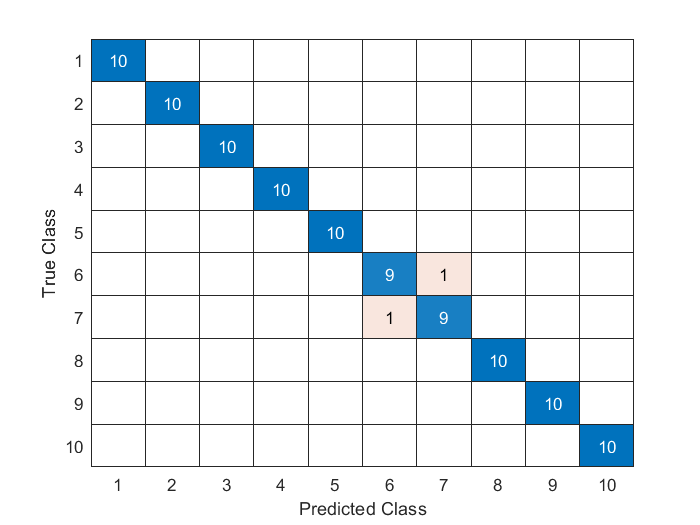

clasificacion(numbers_train,Cuantizadores)

Clasificación de las señales de voz de prueba

disp('Clasificando las señales de prueba')

Clasificando las señales de prueba


La clasificación para las señales 1 fue:     1     1     1     1     1

La clasificación para las señales 2 fue:     2     2     2     2     2

La clasificación para las señales 3 fue:     3     3     3     3     3

La clasificación para las señales 4 fue:     4     4     4     4     4

La clasificación para las señales 5 fue:     7     5     5     5     5

La clasificación para las señales 6 fue:     6     6     6     6     6

La clasificación para las señales 7 fue:     7     7     7    10     7

La clasificación para las señales 8 fue:     8     8     8     8     8

La clasificación para las señales 9 fue:     9     9     9     9     9

La clasificación para las señales 10 fue:    10    10    10    10    10



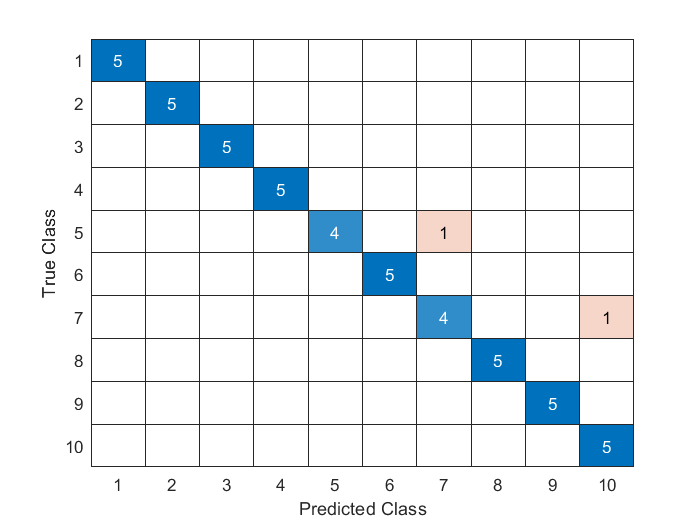

clasificacion(numbers_test,Cuantizadores)

Función que obtiene todos los bloques de un conjunto de muestras para una clase de señal. Por ejemplo, todos los bloques de las muestras de señales "uno".

function blocks = getBlocksAllSamples(samples)
    blocks = Hamming.getBlocks(samples{1});
    for i = 2:length(samples)
            blocks = [blocks; Hamming.getBlocks(samples{i})];
    end
end

Función para clasificar las muestras, ya sea de entrenamiento o de prueba.

Al final muestra su matriz de confusión.

function clasificacion(numbers,cuantizadores)
  prediccion = double.empty; % Valores que el clasificador predice
  real = double.empty; % Valores reales
  for i=1:length(numbers) % Itera sobre las clases de la señal (uno al diez)
    nSeniales = length(numbers{i});
    clasificaciones = zeros(1,nSeniales);
    for j=1:nSeniales % Itera sobre las señales de la clase iésima
      % Aplica procesmiento digital a cada señal
      prenfasis = filter([1 -0.95],1,numbers{i}{j});
      blocks = Hamming.getBlocks(prenfasis);
      r = Correlation.ACorrelation(blocks,12);
      % Obtiene la clasificación de la señal de acuerdo a su distancia
      % mínima a cada cuantizador
      clasificaciones(j) = CuantizadorVectorial.clasificador(r,cuantizadores);
    end
    prediccion = [prediccion,clasificaciones];
    real = [real,ones(1,nSeniales)*i];
    fprintf('La clasificación para las señales %d fue:',i);
    disp(clasificaciones)
  end
  % Genera una matriz de confusión y las muestra
  matConf = confusionmat(real,prediccion);
  confusionchart(matConf)
end